#  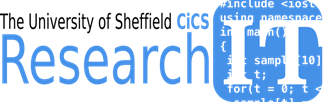                                      

# **Programming with Matlab**

## Outline

- Overview

- Program control structures

- Scripts and functions

- Data Types

- Importing Data

- Case Study

# Overview

- course material

- matlab environment

- getting help

- vectors and matrices

- array indexing and operations

- simple plotting

Materials are available at git hub

[https://github.com/rcgsheffield/matlab-cic6007](https://github.com/rcgsheffield/matlab-cic6007)

we will finish the session by working through a case study+

We will work with an anonymised biomedical data set from the  2007-2008 US National Health and Nutrition Examination Survey (NHANES).  This data is freely available at: [http://www.cdc.gov/nchs/nhanes/nhanes_questionnaires.htm](http://www.cdc.gov/nchs/nhanes/nhanes_questionnaires.htm)

The idea behind choosing this dataset is that delegates from all cultural  and language backgrounds should be able to relate to this data.  Measurements such as arm circumference, height, weight, age are  applicable to everyone.

## Vectors and Matrices

Manual entry array of an array, using the [] bracket notation

- columns separated with a space

- rows separated by a ;

%x= % 1x3 row vector elements separated with spaces
x=[1 2 3]

x =      1     2     3


%y=[] %2x1 matrix  column vector elements separated by ;
y=[sqrt(10); pi^2; sin(pi/4)]

y =     3.1623
    9.8696
    0.7071


%z=[]  % 2x3 matrix
z=[4 5 6; 7 8 9]

z =      4     5     6
     7     8     9


Convert row vector to column vector using transpose ' operator

xt=x'

xt =      1
     2
     3


%

Functions to define array using linspace and the colon notation

u=zeros(2,2);
v=eye(3,3);
w=ones(4,4);
x1=linspace(1,10,5);
y1=(1:1:10);
z1=rand(5,1);
 % linspace(first,last,number of elements)
 %note using transpose


Inspect the work space

 % who list of variables
 who


Your variables are:

ans  u    v    w    x    x1   xt   y    y1   z    z1   




 % whos list showing properties
 
 whos

  Name      Size            Bytes  Class     Attributes

  ans       1x42               84  char                
  u         2x2                32  double              
  v         3x3                72  double              
  w         4x4               128  double              
  x         1x3                24  double              
  x1        1x5                40  double              
  xt        3x1                24  double              
  y         3x1                24  double              
  y1        1x10               80  double              
  z         2x3                48  double              
  z1        5x1                40  double              



## Array operations

We use the [] brackets to assign elements in the array.

The () brackets are used extract elements which we demonstrate below

First create a 6x4 matrix of random numbers.

data=100*rand(6,4)

data =    28.7368   99.1004   59.7211   81.6290
   87.4658   20.5000   49.8385    2.4009
   97.4682   78.3765   92.3006    9.3421
   49.1043   84.1741   80.5217   61.1551
    1.5591   89.9074   28.6094   33.5585
   27.2977   96.3252   98.0060   78.4429



%x1= %extract  a specific element
x1=data(2,2)

x1 = 20.5000

Note below the use of the end keyword

%x2= %get item  at row 6  and column 2
x2=data(end,2)

x2 = 96.3252

x3=data(end-1,end-2)

x3 = 89.9074

## Extracting multiple elements

Create a row vector from the data set

x3=data(2,:)%

x3 =    87.4658   20.5000   49.8385    2.4009


Create a column vector from the data set

x4=data(2:end-1,2)%

x4 =    20.5000
   78.3765
   84.1741
   89.9074


Change values in the array, first create a sub array

v1=data(:,end-1:end)

v1 =    59.7211   81.6290
   49.8385    2.4009
   92.3006    9.3421
   80.5217   61.1551
   28.6094   33.5585
   98.0060   78.4429


v1(1,2)=10

v1 =    59.7211   10.0000
   49.8385    2.4009
   92.3006    9.3421
   80.5217   61.1551
   28.6094   33.5585
   98.0060   78.4429


v1

v1 =    59.7211   10.0000
   49.8385    2.4009
   92.3006    9.3421
   80.5217   61.1551
   28.6094   33.5585
   98.0060   78.4429


change one element of v1

%v1();%
%v1();%
x5=v1(1:end,2)

x5 =    10.0000
    2.4009
    9.3421
   61.1551
   33.5585
   78.4429


x5r=v1(end:-1:1,2) % array in reverse

x5r =    78.4429
   33.5585
   61.1551
    9.3421
    2.4009
   10.0000


## Operations on Matrices

vr=round(10*x3)

vr =    875   205   498    24


[vmax,loc]=max(data)

vmax =    97.4682   99.1004   98.0060   81.6290


loc =      3     1     6     1


Look at the behaviour of the multiply operation, we use a simple row and column vector to illustrate

row=[1 2 3]

row =      1     2     3


col=[4;5;6]

col =      4
     5
     6


row*col

ans = 32

col*row

ans =      4     8    12
     5    10    15
     6    12    18


col.*row

ans =      4     8    12
     5    10    15
     6    12    18


row.*col

ans =      4     8    12
     5    10    15
     6    12    18


Now try a matrix multiply, a pair of simple square matrices clearly illustrates correct matrix multiplication and the behaviour of the dot operator i.e. element wise operation

m1=[1 2; 3 4]

m1 =      1     2
     3     4


m2=[2 0; 0 2]

m2 =      2     0
     0     2



m2*m1

ans =      2     4
     6     8



m2.*m1

ans =      2     0
     0     8


## Multiple Output Function Calls

Multiple outputs are normally returned as a row vector (comma or space separated elements). Functions may also return data as a cell array which we will see later.

numd=numel(data)

numd = 24


%size of data
dsize=size(data)

dsize =      6     4


%numrows, numcols
[numrows,numcols]=size(data)

numrows = 6

numcols = 4


%maximum and index of maximum of data
[maxd,idmax]=max(data)

maxd =    97.4682   99.1004   98.0060   81.6290


idmax =      3     1     6     1


A particularly useful function is the reshape function.

Example create a row vector of 16 values and reshape to a 3x4 matrix

rv=1:12

rv =      1     2     3     4     5     6     7     8     9    10    11    12


%rmat reshape rv as 3x4
rmat=reshape(rv,[3,4])

rmat =      1     4     7    10
     2     5     8    11
     3     6     9    12


Clear the workspace and the variables

clear('u') %clear specific variable note use of quotes
clear %clear the workspace
%clear all to clear the whole workspace
%clc %clear the command window

x=round(20*rand(3,3));
y=round(20*rand(3,3));


# Program Control Structures

## Relational and Logical Operations

For this esction we will use some examples from the numerical analysis folder in particular looking at  problems for finding the root of an equation using the bisection method and the newton-raphson method

Matlab represents true and false by means of the integers 0 and 1.

true = 1, false = 0

If at some point in a calculation a scalar x, say, has been assigned a value, we may make certain logical tests on it:

x == 10 %is x equal to 10?

ans = 2×3 logical array
   0   0   0
   0   0   0


x ~= 10 %is x not equal to 10?

ans = 2×3 logical array
   1   1   1
   1   1   1


x > 10 %is x greater than 10?

ans = 2×3 logical array
   0   0   0
   0   0   0


x < 10 %is x less than 10?

ans = 2×3 logical array
   1   1   1
   1   1   1


x >= 10 %is x greater than or equal to 10?

ans = 2×3 logical array
   0   0   0
   0   0   0


x <= 10 %is x less than or equal to 10?

ans = 2×3 logical array
   1   1   1
   1   1   1


Pay particular attention to the fact that the test for equality involves two equal signs ==. When x is a vector or a matrix, these tests are performed elementwise:

x=[ -2 pi 5; -1 0 1]

x =    -2.0000    3.1416    5.0000
   -1.0000         0    1.0000


x==0

ans = 2×3 logical array
   0   0   0
   0   1   0


x>1,x>=1

ans = 2×3 logical array
   0   1   1
   0   0   0


ans = 2×3 logical array
   0   1   1
   0   0   1


We may combine logical tests, as in

x > 3 & x < 4  %logical and

ans = 2×3 logical array
   0   1   0
   0   0   0


x > 3 | x == -3  %logical or

ans = 2×3 logical array
   0   1   1
   0   0   0


As one might expect, & represents and and (not so clearly) the vertical bar | means or;  also ~ means not as in ~= (not equal), ~(x>0), etc.

%try x>3 or x==-3 or x less than or equal to -5


One of the uses of logical tests is to mask out certain elements of a matrix.

## Find function

Find returns the indices of the vector that are non-zero. When used with relational operators it will return the indices of a vector satisfying a given condition.

%TODO use find function to return indices for which x values are greater than or equal to pi  

 x

x =    -2.0000    3.1416    5.0000
   -1.0000         0    1.0000


 indpi=find(x>=pi)

indpi =      3
     5


 x(3)

ans = 3.1416

 x(5)

ans = 5

Results of the find() function can be used as an index vector to select or eliminate data which meets a certain criteria. 

       a = [ 1.3 5.6  7.8  2.0  4.0 3.8   2.5]

a =     1.3000    5.6000    7.8000    2.0000    4.0000    3.8000    2.5000


     % create k find values of a<3 (k contains indices)
  %     %create a new vector c made up of the kth  elements of a in that order. 
k=find(a>3)

k =      2     3     5     6


anew=a

anew =     1.3000    5.6000    7.8000    2.0000    4.0000    3.8000    2.5000


anew(k)=3

anew =     1.3000    3.0000    3.0000    2.0000    3.0000    3.0000    2.5000


anew

anew =     1.3000    3.0000    3.0000    2.0000    3.0000    3.0000    2.5000


## Program Control Using Loop Control and Conditional Statements

There are occasions that we want to repeat a segment of code a number of different times (such occasions are less frequent than other programming languages because of the : notation).

mysum1=0.0

mysum1 = 0

mysum2=0;
for v=1:5
   mysum1=mysum1+v
   mysum2=mysum2+(1/v);
end

mysum1 = 1

mysum1 = 3

mysum1 = 6

mysum1 = 10

mysum1 = 15

For the above loop the commands between the lines starting `for `and `end` are repeated with v being given the value 1 the first time through, 2 the second time, and so forth, until v = 5. The interval can easily be changed using the colon notation.

%using a function and changing the interval
mysum2=0.0

mysum2 = 0

for v=1:2:11
   mysum2=mysum2+sin(v/(2*pi)) ;
end

%pause;

mysum3=0;
w=[1 2 5 7 8 9 11 ];
for v = w
   mysum3=mysum3+v ;
end

mysum4=0;
A=rand(4,3)  %each column of the matrix will be passed in turn

A =     0.6921    0.8379    0.2754
    0.5635    0.6253    0.2960
    0.5775    0.3284    0.0285
    0.6193    0.2175    0.6720


for v = A
   mysum4=mysum4+v 
end

mysum4 =     0.6921
    0.5635
    0.5775
    0.6193


mysum4 =     1.5300
    1.1888
    0.9059
    0.8368


mysum4 =     1.8054
    1.4847
    0.9344
    1.5088


## if...then...else...end

This allows us to execute different commands depending on the truth or falsity of some logical tests. To test whether or not e is greater than, or equal to, e:

a = pi^exp(1), c = exp(pi), a^c, c^a

a = 22.4592

c = 23.1407

ans = 1.8715e+31

ans = 4.3928e+30

%TODO set correct b value if a>=c to sqrt(a^2-c)
if a>=c
    b=sqrt(a^2-c^2)
end

so that b is assigned a value only if a >= c. A more common situation is

if a >= c
    b = sqrt(a^2 - c^2)
else
    b=0
end

b = 0

which ensures that b is always assigned a value and confirming that a < c. A more extended form is

if a >= c
    b = sqrt(a^2 - c^2)
elseif a^c > c^a
    b = c^a/a^c
else
    b = a^c/c^a
end

b = 0.2347

The general for m for the if.. else if structure is

% if logical test 1
%     Commands to be executed if test 1 is true
% elseif logical test 2
%     Commands to be executed if test 2 is true but test 1 is false
%     ...
% end

## While Loop

There are some occasions when we want to repeat a section of Matlab code until some logical condition is satisfied, but we cannot tell in advance how many times we have to go around the loop. This we can do with a while...end construct.

Example: What is the greatest value of n that can be used in the sum

1^2 + 2^2 +..... � +(n-2)+ (n-1)^2 + n^2

and get a value of less than 100?

S = 1; n = 1;
while S+ (n+1)^2 < 200
    n = n+1; S = S + n^2;
end
[n, S]

ans =      7   140


The root finder using the bisection method is an excellent illustration of usage of the while loop

%addpath('../matlab_examples/numericalanalysis/root_bisection/')
%edit root_bisection; %inspect the script


root_bisection;

 The root is :
    2.0946



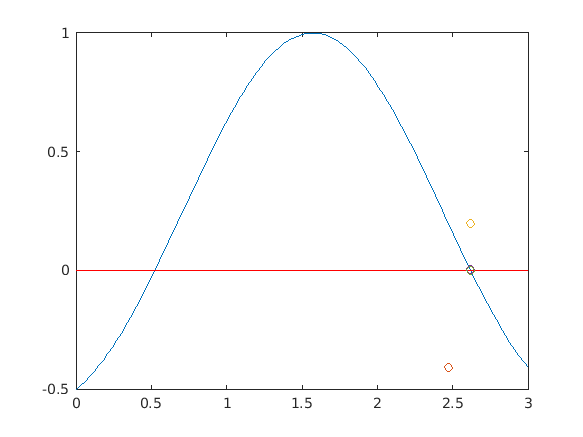

   -0.5288

    0.1440

    0.0028

   2.1966e-06

 The root is :
    2.6180




clear all;
addpath('../matlab_examples/numericalanalysis/root_newton')
edit root_newton

root_newton;

# Using Functions and Scripts

Function files are a combination of the ideas of script  and mathematical functions.

1. Decide on a name for the function, making sure that it does not conflict with a name that is already used by Matlab.

2. The first line of the file must have the format:

`function [list of outputs]= function name(list of inputs)`

3. Document the function. That is, describe the purpose of the function and how it can be used. These lines should be preceded by % which signify that they are comment lines that will be ignored when the function is evaluated.

4. Finally include the code that defines the function. This should be interspersed with sufficient comments to enable another user to understand the processes involved.

Consider the differences between funcntions and scripts

- A sequence of matlab commands can be put into a file which can later be executed by invoking its name.  The files which have .mextensions are recognised by Matlab as *Matlab**Script*or *Matlab** Function*files.

- If an mfile contains the keyword **function** at the beginning of its first line it is treated as a Matlab function file.

- Functions make up the core of Matlab. Most of the Matlab commands “apart from a few built-in ones”  are in fact matlab functions. 

Use the matlab_examples numerical analysis root_newton Run the root newton example as a script

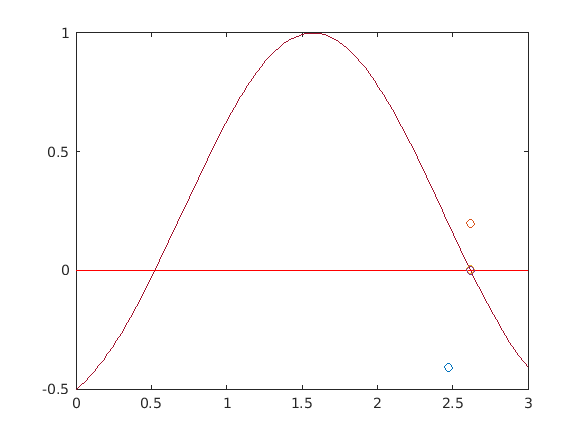

   -0.5288

    0.1440

    0.0028

   2.1966e-06

 The root is :
    2.6180



root_newton_script

Run the newton solver as a function

clear all


- Most Matlab commands are in fact functions (provided in .m files of the same name) residing in one of the Matlab path directories. See path command.

- Matlab searches for scripts and files in the current directory first and then in the Matlab path going from left to right. If more than one function/script exists with the same name, the first one to be found is used.  “***name-clash***”  

- To avoid inadvertent name-clash problems use the which command to check if a function/script exists with a name before using that name as the name of your own function/script or to find out that the function you are using is really the one you intended to use!

-      Example :  *which **mysolver*

- lookfor and what commands can also help locate Matlab functions. 

- Having located a function use the type command to list its contents.

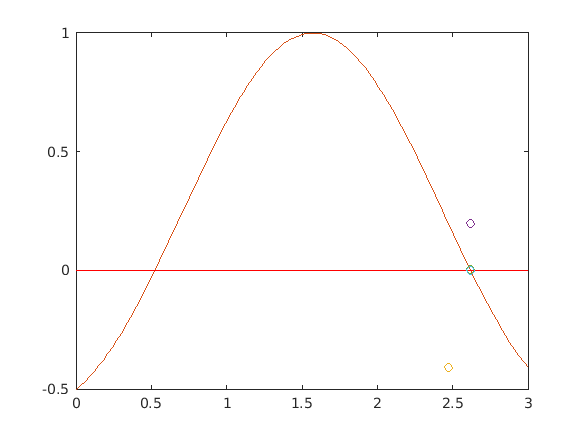

   -0.5288

    0.1440

    0.0028

   2.1966e-06

 The root is :
    2.6180



a = 0;
b = 3;
hf= @testf;
hderivf= @testderivf;
root_newton_function(hf,hderivf, a, b);

%cd ../../../presentations/



## Differences between functions and scripts

- Matlab functions **do not**use or overwrite any of the variables in the workspace as they work on their own private workspace. 

- Any variable created within a function is not available when exited from that function. ( Exception to this rule are the Global and Persistent variables)

# Data Types

Numeric

- Complex, 

- double precision

- Single precision

- Integer 

- Boolean

- Character String

- Java Classes

- User Defined MatlabClasses

  **ORGANIZATIONAL ATTRIBUTES**

- Multi-dimensional Matrices

- Sparse Matrices

- Cell Arrays

- Structures & Objects

**Complex double precision matrices**

- This is the default storage mode.

- A scalar is really a 1x1 matrix with the imaginary part set to zero.

- Any expression which evaluates to a complex value returns complex results automatically

- The following are two methods of expressing a complex number;


%X = complex( 1.2 , 3.4 )
%X = 1.2+3.4i

- Warning i and j has this special meaning which will be lost if you name your variables as iand j . So don’t !

- Matlab keeps track of complex vs real issues and does the necessary conversions. Therefore you need not worry about it.

## Logical Matrices

- Results of relational operations return logical matrices ( with 1’s and 0’s only )

- These matrices are primary useful for program control structures and they can implicitly be used as masks in vectorisation

a = rand (1,10);   
b = rand(1,10); d= 1:10;
%c = a < b    % c is a logical matrix.
a(c) = [ ]   % eliminate elements where a<b 

Unrecognized function or variable 'c'.

## Character Strings

A Character string is simply a 1 by n array of characters.

name='tommy'
%TODO
%friends = [ 'tommy' ; 'billy'  ;  'tim  ' ]

 Note that all items must have the same length by padding them with blanks where necessary. This ensures that the matrix convensionis not violated. Where as; 

%TODO
% friend = [ 'Alexandra' , 'jim' ] 

is a valid construct as the resultant structure is simply an array. In this case friend(3) is ‘e’ for example. 

## Multi-dimensional Arrays

- •These are arrays with more than 2 subscripts

- •They can be generated by using one of the following functions;

 ` zeros  ,  ones  ,  rand ,  randn`

 R = zeros ( 10,20,20);
 A = ones( 10,20)
 R(:,:,1) = A
 

## Structures

These are Matlab arrays with elements accessed by field names. They are useful for organizing complex data with a known structure. Structures can be nested.

Creating a structure

 order.number= 105; order.year=2003; order.title='Smith';
 %TODO
 %order(2)= %struct( 'number',207,'year',2003, 'title','Jeff Brown') 

Deleting fields

 %TODO
 %use rmfield to remove the year field from order
% modorder = ;

## Cell Arrays

Cell arrays are Matlabarrays whose individual elements are free to contain different types & classes of data. These elements need not ‘and usually are not’ of same type, size or shape. They are useful for storing data that can not otherwise be organized as arrays or structures.  Cell arrays can be nested.

Create a 4by2 cell matrix. Each cell can contain any type and size of data

 C = cell(4,2)  
 

Create (4by1)cell array B and assign values:

 B = { [1,2] , [ 4 5 ; 5 6] , 0.956 , 'range values'} 
 D = { [1,2] , [3,4], [5,6] } 
 

Build a (1by5) cell-array M containing 5 elements,  one cell at a time:

M{1} = 1 ; M{2}= [1 2 3] ; M{3} =[1 2;3 4] ;
M{4} = rand(10,10) ; M{5}='title' ;
cell2mat(D) %elements of cell array need to be of same data type!


# Importing Data

Matlab provides a range of tools for importing a variety of formats including text, spreadsheets, images, audio files, xml formats and general pupose tools for developing bespoke file readers.

One of the first methods is the save and load command which can be used to save and load workspace variables.

For example to save all the current work space variables use the command

%TODO
%save(...)

to save a specific variable for example the M cell array

%TODO
%save the M matrix
%save()

Note variables to be saved are indicated in single quotes and there is a comma separated list of variables.

[Data Import and Export](https://uk.mathworks.com/help/matlab/data-import-and-export.html)

The simplest way to import data is to use the data import wizard provided through the matlab workbench there is a button to start the wizard on the home bar of the Matlab workbench. When the wizard starts the user is presented with a file input dialog, the dialog which follows presents a section of the input file and allows the user to set separators between each of the fields, set the number of headerlines. Data can be read in directly using the importdata command. A useful feature of the data import wizard is the script generation utility for generating a script used to import the data file. 

[importdata](https://uk.mathworks.com/help/matlab/ref/importdata.html)

data=importdata('../data/field.dat')

data =     1.2000    5.0000    3.4000
    1.5000    4.0000    2.0000
    1.6000    3.6000    1.4000
    2.0000    3.3000    1.1000
    2.6000    2.4000    1.8000
    2.7000    2.0000    2.6000
    2.7500    1.6000    2.8000
    2.8000    1.3000    2.6000
    2.7600    1.5000    2.3000
    2.6000    1.8000    2.0000


In the following case study we will use the readtable command which creates a table by reading column oriented data from a file.

## Import data from a single file containing heterogeneous data.

We will use a table to hold the results. Tables are for storing heterogeneous tabular data.

% Inspect the data file:
%addpath('../matlab_examples/casestudies/health/');
cd ../matlab_examples/casestudies/health/
edit('MedicalData.txt'); 

% Use READTABLE to import the data. If unfamiliar with this function, this
% is a good opportunity to demonstrate the use of F1/searching in the
% documentation. It's also worth mentioning the table of import/export
% functions at this point. Search for "Supported File Formats" to bring up
% this table in the documentation, and point out the use of the READTABLE
% function.
%TODO
%use readtable specify tab Delimeter '\t' write data to medData
%medData = 

% Why are people so old? They're not really, it's just that Age is recorded
% in months. So we might want to convert the data.

% Table variables are accessed using the dot syntax (similar to structures,
% if people are familiar with those).
medData.Age = medData.Age/12; % Note: age is recorded in months.


Unable to resolve the name medData.Age.

% Best practice would be to have comments explaining any "magic numbers" in
% the code. For example, where did the 12 come from?
% As an alternative, we could use "self-commenting" variables, e.g.
months2years = 1/12;

% Compute pulse pressure and store this as an additional table variable.
medData.BPDiff = medData.BPSyst1-medData.BPDias1;

% What about naming conventions? Generally we would use camel case.
% Table/structure variable names can be capitalised. Try to get people to
% agree on some convention, and then stick with it.

## Plotting vectors and annotating graphs.

How  can we visualise the information we have just computed? It's worth  showing all available plots from the Plots tab at this point.

figure % New figure.
%TODO
% Basic discrete plot and annotations.
%scatter plot medData.Age v medData.BPDiffxlabel age ylabel pressure


## Low-Level File I/O.

Suppose we have data from a file containing numeric data. How can we read this in efficiently?  Three-step process, using textscan for text files.

% The open/close statements are essential. Ask the audience: what happens
% if the file remains open? Why is it good practice to ensure files are
% closed after use?
fileID = fopen('HeightWaistData.txt');

% The next step is critical. This is where you can control the precise
% format MATLAB will use to import the data. See the documentation for
% textscan for more details.
dataFormat = '%f %f'; % Two columns of numeric (double, floating point) data.
heightWaistData = textscan(fileID, dataFormat, ...
    'Headerlines', 1, 'Delimiter', '\t');

fclose(fileID);

% You can ask here: do we really need to use DOUBLE to store the data? How
% many significant figures are there? What else could we use to save
% memory? (SINGLE, specified via %f32 in TEXTSCAN).

## Cell Arrays.

The data from textscan is  imported as a cell array in the MATLAB workspace. The data is imported  into a 1x2 cell array (each column of data is stored in a separate  cell). A useful visualisation function for inspecting cell arrays is  CELLPLOT. This can help to alleviate misunderstanding of how cell arrays work.

figure; cellplot(heightWaistData)

## Converting Data Types.

All the elements of a MATLAB array must be the same type. This rule is particularly important when attempting to concatenate data of different types (e.g. strings  and numbers). In the documentation, you can show the reference page at:  MATLAB -> Language Fundamentals -> Data Types -> Data Type  Conversion which has a comprehensive list of conversion functions.

% Convert the data to a useful format.
HW = cell2mat(heightWaistData);

% Alternatively, you can show HW = [heightWaistData{1}, heightWaistData{2}]
% or even HW = [heightWaistData{:}]. However, this will require explanation
% of cell indexing (curly brackets give contents) versus standard array
% indexing (round brackets give a sub-cell array).

% Try computing the mean of each variable.
disp(mean(HW))

% Why does this not give us "proper" values? NaNs - missing data. We would
% like to remove them to obtain proper results. However, we need to know
% how to index into arrays before attempting this.

## Accessing Data in Arrays.

Data in MATLAB can be accessed using several indexing methods. Generally, row/column, or  subscript, indexing is the natural method to introduce first. Useful  tips here include the use of the "end" keyword, as well as the use of  the colon as an index as a shortcut for 1:end. Emphasise that row/column indices do not have to be scalar values.

% Extract height and waist data separately.
Height = HW(:, 1);
Waist = HW(:, 2);

## Dealing with Missing Data.

This requires use of logical indexing (passing logical arrays as indices to other  arrays). The key function here is ISNAN (it's worth showing the  reference page IS* in the documentation which has a list of all useful  functions for detecting certain conditions or states). Also, you can  show the reference page >> doc ops which has a list of all  MATLAB's operators, including logical operators which are required here.

% Remove any observations containing NaNs.
badObs = isnan(Height) | isnan(Waist);
cleanHWData = HW(~badObs, :);
disp(mean(cleanHWData))

## Importing Data from Multiple Files.

We have  seen how to import homogeneous and heterogeneous data from single files. Often, researchers have multiple data files with similar formats, so it is useful to know how to batch process a list of files. The  documentation contains a list of functions for performing file and  directory management, such as changing directory, moving files, and  creating directories: MATLAB -> Data and File Management -> File  Operations -> Files and Folders.

% The first step is to form a list of files to import data from.
% Warning: be careful here to avoid platform-dependent issues. Use of
% FILESEP is generally recommended to avoid hard-coding slashes or
% backslashes. This should recover a list of .txt files in the "ArmsLegs"
% directory.
fileInfo = dir(['ArmsLegs', filesep, '*.txt'])
fileList = {fileInfo.name}

## Programming Constructs.

Here, we need to  operate on each data file. We know how many data files there are, so a  for-loop is appropriate. Use ISKEYWORD to display a list of MATLAB's  programming keywords. You may want to mention other common constructs  such as if-elseif-else, try-catch, switch-case and while-loops.

## Structure Arrays.

We would like to store the name of each file (a string) as well as the  numerical data it contains (a matrix with three columns) together in the same variable. Tables are not suitable for this, because in a table all variables must have the same number of observations. We can use a  structure array instead. This allows access to the data using the same  convenient dot syntax we used for tables, but also allows storage of  mixed-size data. (However, structures have far less available  functionality associated with them than tables. For example, SORTROWS  comes with tables but not with structures.)

% You can show the loop being performed sequentially to begin with, and
% then initiate a discussion about the Code Analyzer warning that comes up.
% This should lead to a discussion about preallocation, which can be shown
% explicitly using the STRUCT function, for example. However, in this case
% it's much easier just to do the loop backwards and therefore have the
% preallocation performed implicitly.
for k = numel(fileList):-1:1
    ArmsLegs(k).FileName = fileList{k};
    ArmsLegs(k).Data = dlmread(['ArmsLegs',filesep,fileList{k}], '\t', 1, 0);
end

## Concatenation.

After reading all the data,  we would like to merge it into one variable so that we have all of the  body measurements together. It's worth spending a bit of time talking  about concatenation with square brackets [], and then mention that for  comma-separated lists, you can use VERTCAT, HORZCAT and CAT.

ALData = vertcat(ArmsLegs.Data);

## Logical Indexing.

We have seen logical  indexing above. We used it to detect and remove missing values. It is an important and widely applicable MATLAB language feature. For example,  we might want to visualise the split/separation between two different  groups in our population, e.g. males and females.

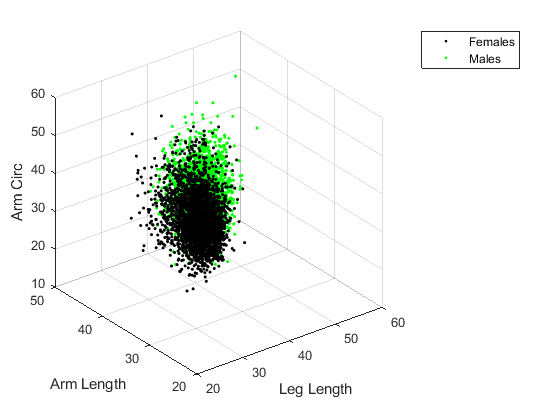

females = strcmp(medData.Sex, 'F');
figure
scatter3(ALData(females, 1), ALData(females, 2), ALData(females, 3), 'k.')
hold on % Ask what happens if we don't use HOLD here.
scatter3(ALData(~females, 1), ALData(~females, 2), ALData(~females, 3), 'g.')
hold off
xlabel('Leg Length')
ylabel('Arm Length')
zlabel('Arm Circ')
legend('Females', 'Males')

## Saving and Loading MAT-Files.

We have spent a lot of time and effort into importing our data effectively. Do we  really want to repeat this effort if we need the data again? Probably  not. You can save all the data to disk using a MAT-file (designed to  hold MATLAB data and variables). Loading from MAT-files is also faster  in general terms than running file import code. The idea is to import  the data only once, and then save it to a MAT-file for future use or  distribution to others.

% Save data to a MAT-file.
save('S01_HealthData.mat')

# Next Session

- debugging

- performance